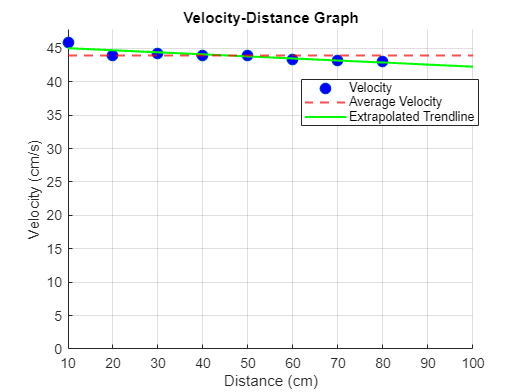

% Distance and velocity data
distance = [80, 70, 60, 50, 40, 30, 20, 10]; % Distance (cm)
velocity = [43.1, 43.2, 43.4, 43.9, 43.9, 44.3, 43.9, 45.9]; % Velocity (cm/s)

% Calculate the average velocity
average_velocity = mean(velocity);

% Define extra points for extrapolation (e.g., extending distance by 20 cm beyond data)
extra_distance = [90, 100]; % Additional distances for extrapolation
all_distance = [distance, extra_distance]; % Combine original and extra distances

% Fit a linear model for extrapolation
p = polyfit(distance, velocity, 1); % Linear fit (1st degree polynomial)
extrapolated_velocity = polyval(p, all_distance); % Apply model to original and extra distances

% Plotting
figure;
hold on;

% Plot velocity points
plot(distance, velocity, 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'b', 'DisplayName', 'Velocity');

% Add average velocity line
yline(average_velocity, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Average Velocity');

% Plot extrapolated line
plot(all_distance, extrapolated_velocity, 'g-', 'LineWidth', 1.5, 'DisplayName', 'Extrapolated Trendline');

% Axis labels and limits
xlabel('Distance (cm)');
ylabel('Velocity (cm/s)');
ylim([0 max([velocity, extrapolated_velocity]) + 2]); % Start y-axis from 0

% Title and legend
title('Velocity-Distance Graph');
legend('show');
grid on;
hold off;